# FFT Examples - Change the length of the FFT

Plot the frequency representation of the signal using the N-FFT function for different N values.

**Parameters** 

- 
$$x[n] = cos(2 \pi F_{0} nT_s) + cos(2 \pi F_1 n T_s)$$


- F_0 = 1 [kHz]

- F_1 = 5.123 [kHz]

- F_s = 16 [kHz];

- N=[8, 16, 32, 256]

**FFT Function (reference: "*****help fft")***

Y = fft(X,n) returns the n-point DFT. If no value is specified, Y is the same size as X.

- If X is a vector and the length of X is less than n, then X is padded with trailing zeros to length n.

- If X is a vector and the length of X is greater than n, then X is truncated to length n.

- If X is a matrix, then each column is treated as in the vector case.

- If X is a multidimensional array, then the first array dimension whose size does not equal 1 is treated as in the vector case.

## Clear

clc;        % 'clc' cleras all the text from the Command Window
clear;      % 'clear' removes all variables from the current workspace
close all;  % 'close all' deletes all figures whose handles are not hidden.

## Parameters

len = 32;
Fs = 16e3;
Ts = 1/Fs;
F0 = 1000;
F1 = 5123;
N = [8, 16, 32, 256];

## Exercise

n = 0:len-1;
x = cos(2*pi*F0*n*Ts) + cos(2*pi*F1*n*Ts);

Xf0 = fft(x,N(1))/length(x);
Xf1 = fft(x,N(2))/length(x);
Xf2 = fft(x,N(3))/length(x);
Xf3 = fft(x,N(4))/length(x);

Xf0 = abs(Xf0);
Xf1 = abs(Xf1);
Xf2 = abs(Xf2);
Xf3 = abs(Xf3);

Xf0 = fftshift(Xf0);
Xf1 = fftshift(Xf1);
Xf2 = fftshift(Xf2);
Xf3 = fftshift(Xf3);


## Plot

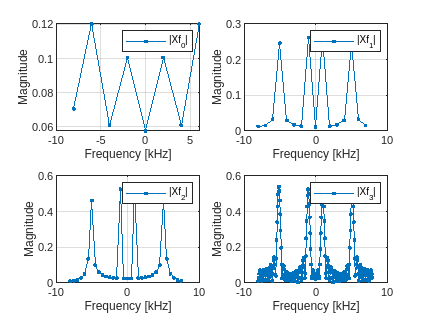

f_ax0 = (-N(1)/2:1:N(1)/2-1)/N(1)*Fs/1e3;
f_ax1 = (-N(2)/2:1:N(2)/2-1)/N(2)*Fs/1e3;
f_ax2 = (-N(3)/2:1:N(3)/2-1)/N(3)*Fs/1e3;
f_ax3 = (-N(4)/2:1:N(4)/2-1)/N(4)*Fs/1e3;

figure
subplot(2,2,1)
  plot(f_ax0, Xf0, '.-')
  grid on
  legend('|Xf_0|')
  xlabel('Frequency [kHz]')
  ylabel('Magnitude')
subplot(2,2,2)
  plot(f_ax1, Xf1, '.-')
  grid on
  legend('|Xf_1|')
  xlabel('Frequency [kHz]')
  ylabel('Magnitude')
subplot(2,2,3)
  plot(f_ax2, Xf2, '.-')
  grid on
  legend('|Xf_2|')
  xlabel('Frequency [kHz]')
  ylabel('Magnitude')
subplot(2,2,4)
  plot(f_ax3, Xf3, '.-')
  grid on
  legend('|Xf_3|')
  xlabel('Frequency [kHz]')
  ylabel('Magnitude')